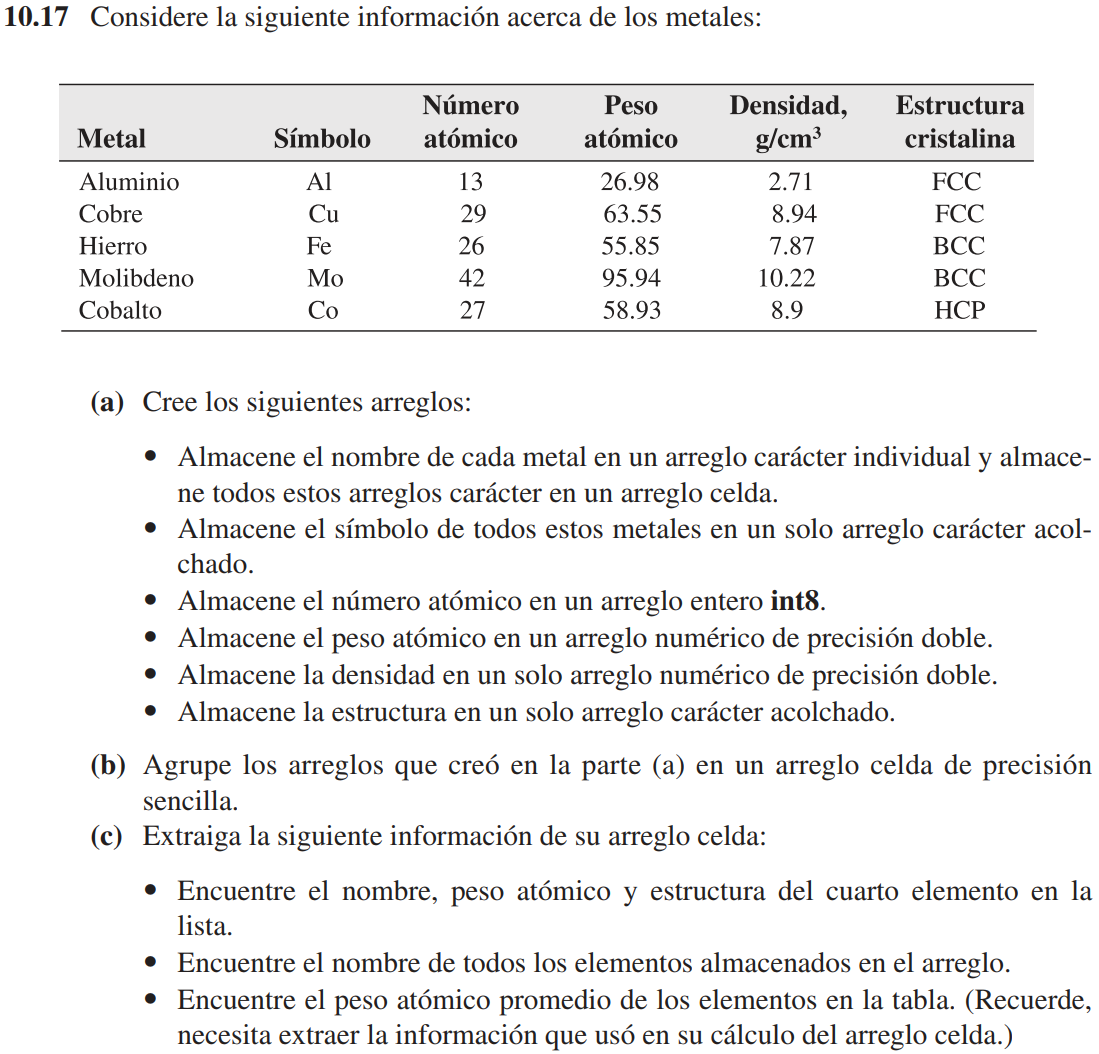

clear

% Literal a.
metal1 = 'Aluminio'; metal2 = 'Cobre'; metal3 = 'Hierro'; metal4 = 'Molibdeno';
metal5 = 'Cobalto';
metalNames = {metal1 metal2 metal3 metal4 metal5}';

metalSymbol = char('Al','Cu','Fe','Mo','Co');

atomicNumber = int8([13 29 26 42 27]');

atomicWeight = [26.98 63.55 55.85 95.94 58.93]';

metalDensity = [2.71 8.94 7.87 10.22 8.9]';

crystalStructure = char('FCC','FCC','BCC','BCC','HCP');

% Literal b.
metalCell = {metalNames metalSymbol single(atomicNumber) single(atomicWeight) ...
    single(metalDensity) crystalStructure}

% Literal c.
element4 = {metalCell{1}{4,:} metalCell{4}(4,:) metalCell{6}(4,:)}

elementsName = metalCell{1}

meanAtomicWeight = mean(metalCell{4})

Para no repetir código se utilizarán los arreglos creados en el literal **a** del ejercicio anterior.

metalStruct.metalNames = metalNames;
metalStruct.metalSymbol = metalSymbol;
metalStruct.atomicNumber = atomicNumber;
metalStruct.atomicWeight = atomicWeight;
metalStruct.metalDensity = metalDensity;
metalStruct.crystalStrucure = crystalStructure;
metalStruct

maxDensity = max(metalStruct.metalDensity)

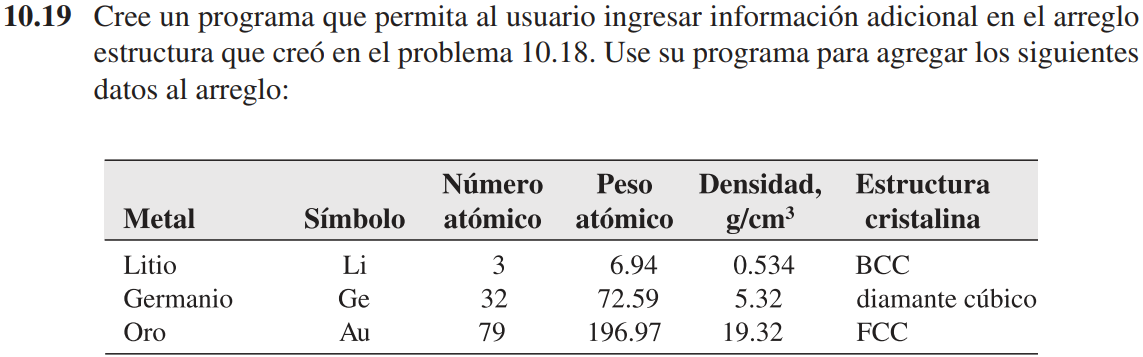

clc

n = menu('¿Desea añadir información?','Si','No');

while n == 1
    metalStruct.metalNames{end + 1} = input('Nombre del metal: ','s');
    metalStruct.metalSymbol = char(metalStruct.metalSymbol,...
        input('Símbolo del metal: ','s'));
    metalStruct.atomicNumber(end + 1) = input('Número atómico: ');
    metalStruct.atomicWeight(end + 1) = input('Peso atómico: ');
    metalStruct.metalDensity(end + 1) = input('Densidad del metal: ');
    metalStruct.crystalStrucure = char(metalStruct.crystalStrucure,...
        input('Estructura cristalina del metal: ','s'));
    
    disp('Información añadida.')
    n = menu('¿Desea añadir información?','Si','No');
end

maxAtomicWeight = max(metalStruct.atomicWeight)